#### Configure parameters

setup_rotpen

K =      0     0     0     0


cls_poles =      0     0     0     0


 
Balance control gain: 


K =      0     0     0     0


Swing-up Parameters: 
   Er = 0 J
   a_max = 0 m/s^2


#### Run simulation

#### Parameters Controllers

L= 16.8 ;

#### Initial Conditions

x0=[0;0;0.1;0];
c_1=1;
c_2=4;

parametrosSim.StopTime = '10';
parametrosSim.Solver = 'ode1';
parametrosSim.FixedStep = '0.001';
parametrosSim.ReturnWorkspaceOutputs = 'on';
out = sim('stable.slx',parametrosSim);

#### Figures

figStates= figure;
plot(out.t,out.x(:,4),out.t,out.x(:,3),out.t,out.x(:,2),out.t,out.x(:,1),'LineWidth',1)
h1=legend('$\dot{x_3}$','$x_3$', '$\dot{x_1}$', '$x_1$')

h1 =   Legend ($\dot{x_3}$, $x_3$, $\dot{x_1}$, $x_1$) with properties:

         String: {'$\dot{x_3}$'  '$x_3$'  '$\dot{x_1}$'  '$x_1$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6851 0.7123 0.2006 0.1877]
          Units: 'normalized'

  Show all properties


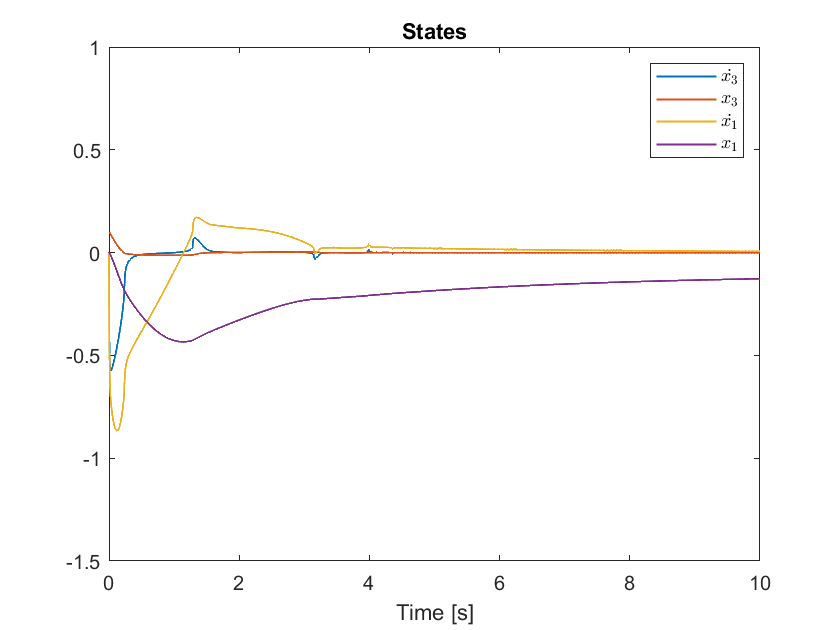

set(h1, 'Interpreter', 'latex');
ylim([-1.5 1])
title(strcat("States"))
xlabel('Time [s]')

%===========================================================================

figTau= figure;
plot(out.t,out.tau,'LineWidth',1)
h2='\tau'

h2 = '\tau'

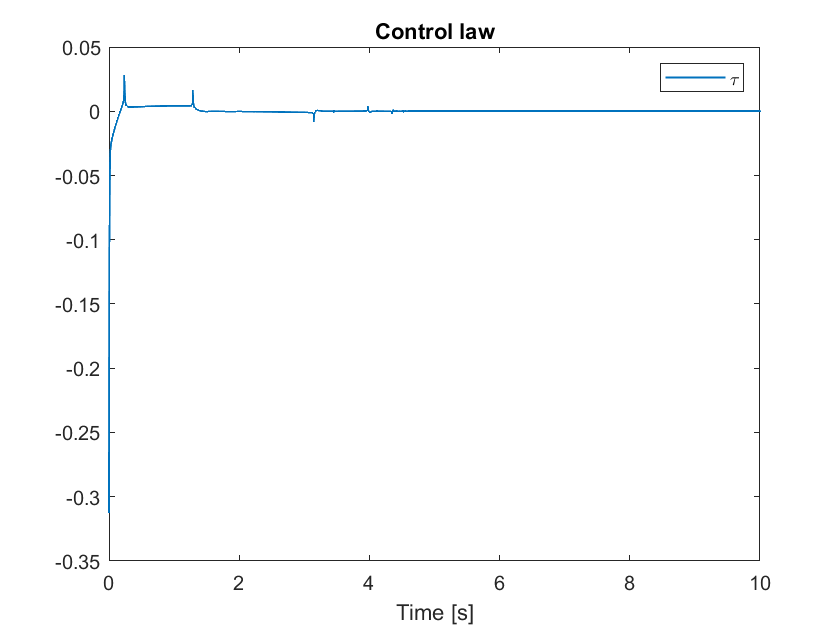

title('Control law')
legend(h2)
xlabel('Time [s]')

%===========================================================================

fignuMu= figure;
plot(out.t,out.nuMu,'LineWidth',1)
h2='\nu_{\mu}'

h2 = '\nu_{\mu}'

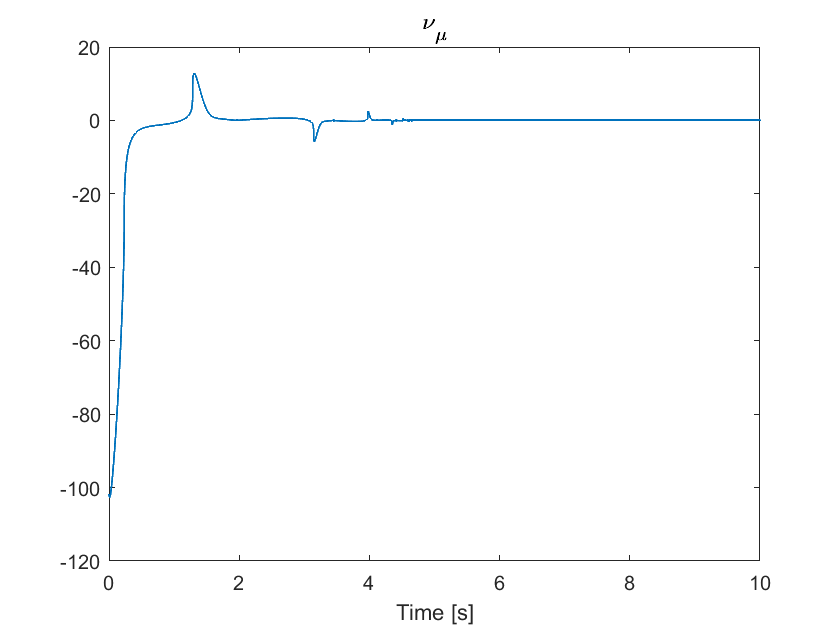

title(h2)
xlabel('Time [s]')


cd('C:\Users\5470\OneDrive\P\Universidad\Septimo Semestre\Servicio\doublenuevo\doubleFuruta\resources\matlab\figures')

print(figStates,'states_2dofpendulum','-dpng');

print(figTau,'tau_2dofpendulum','-dpng');

print(fignuMu,'nuMu_2dofpendulum','-dpng');


cd('C:\Users\5470\OneDrive\P\Universidad\Septimo Semestre\Servicio\doublenuevo\doubleFuruta\resources\matlab\')
warning("Figures printed")